2차원 그래프

MATLAB을 이용하여 여러 유형의 2차원 그래프를 생성하고 그래프의 형식을 지정하는 방법에 대해 기술한다.

5.1 plot 명령어

2차원 그래프를 생성하는 데 사용되는 명령어

plot(x, y)

x : x 좌표값들을 가진 벡터

y : y 좌표값들을 가진 벡터

x, y 두 벡터로부터 형성되는 순서쌍을 그래프에 점으로 나타내고 점들을 직선으로 잇는다.

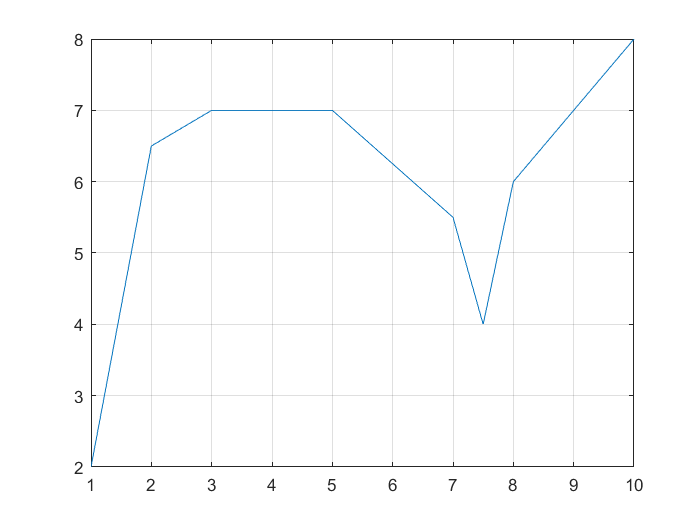

x=[1 2 3 5 7 7.5 8 10];
y=[2 6.5 7 7 5.5 4 6 8];
plot(x,y)
grid on % x-y 격자 표시 하기.

plot 명령어의 옵션으로 선 색깔과 종류, 데이터 표식(marker) 모양 등을 지정할 수 있다. 

plot(x, y, ‘line specifiers',  'PropertyName',  PropertyValue)

line specifiers : 선과 marker의 모양∙색 지정

PropertyName : 선의 굵기, marker의 크기∙테두리 ∙배경 색 지정

PropertyValue : 위의 속성(선의 굵기, marker의 크기∙테두리 ∙배경 색)으로 지정된 속성의 값.

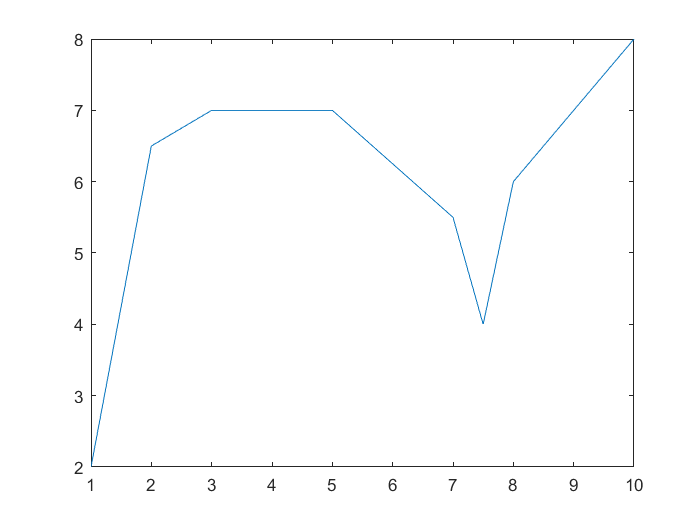

x=[1 2 3 5 7 7.5 8 10];
y=[2 6.5 7 7 5.5 4 6 8];
plot(x, y); % 파란 실선(기본 설정)

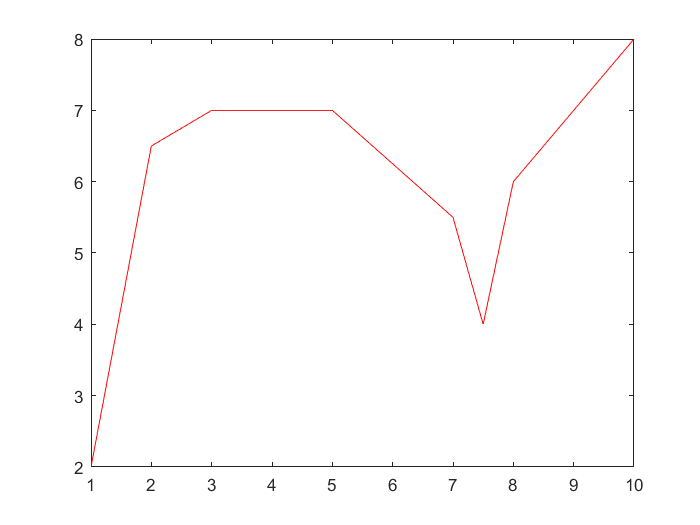

plot(x,y,'r') % 빨간 실선

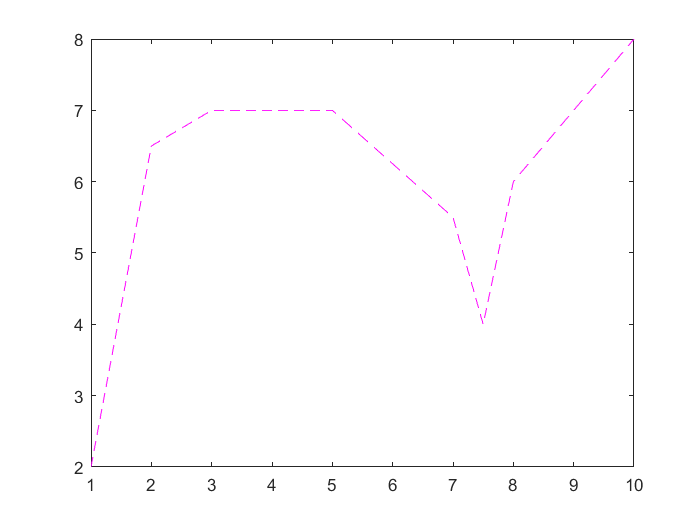

plot(x,y,'--m') % 데이터 값을 magenta color 파선으로 표시

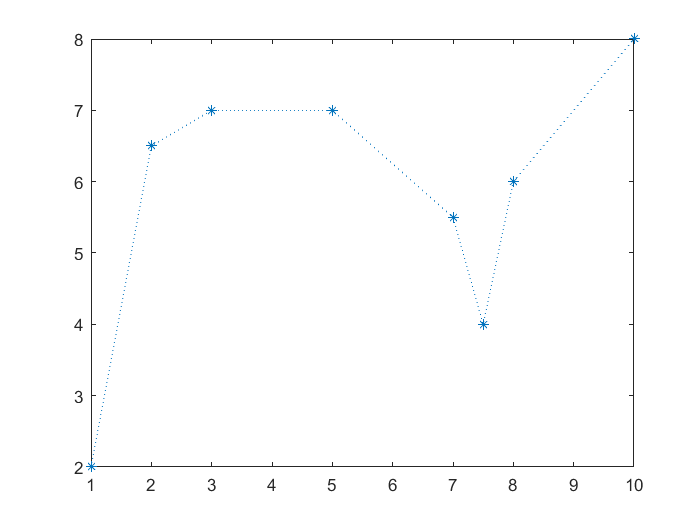

plot(x,y,':*') % 데이터 값을 blue color * 모양으로 표시

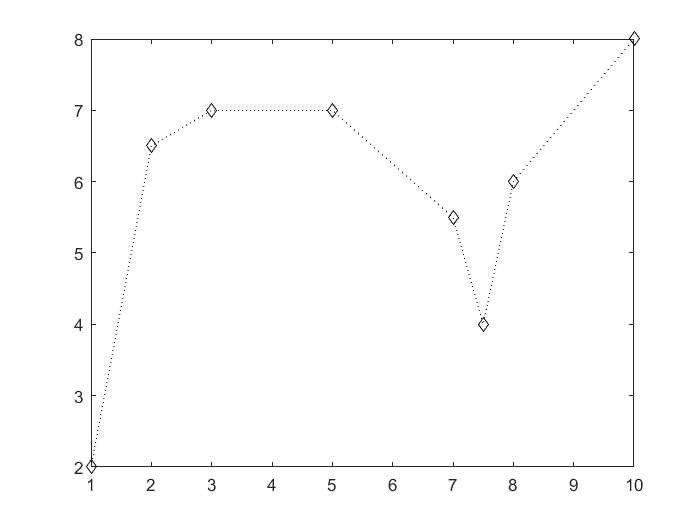

plot(x,y,'k:d') % 데이터 값을 black color 다이아모드 모양으로 표시 후 점선으로 연결

그래프 속성(property) 지정

LineWidth : **선의 ****굵기**** 지정,  point 단위를 쓴다. (기본 0.5 pt)**

MarkerSize: **marker****의 ****크기**** 지정, point 단위를 쓴다. (보통 10 pt)**

속성 지정의 예 

plot(x,y,'-mo', ‘MarkerSize',12,  'LineWidth', 2) 

원형 marker 표시, magenta색  실선

marker의 크기: 12 point

선 두께 2 point

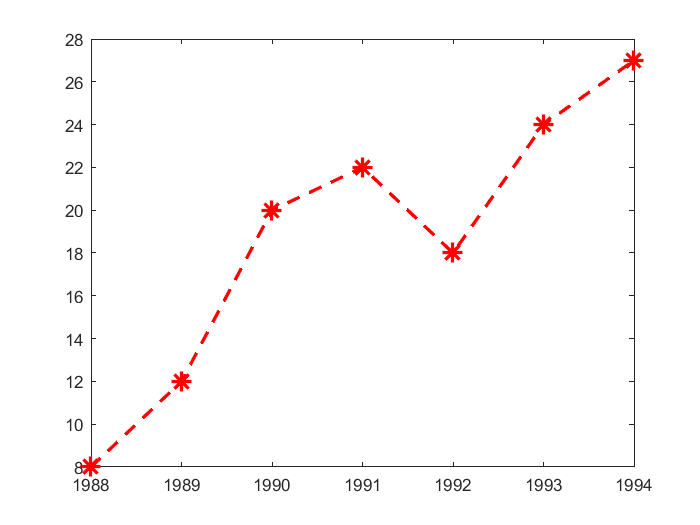

yr=[1988:1994];
sales=[8 12 20 22 18 24 27];
plot(yr, sales, '--r*', 'LineWidth', 2, 'MarkerSize', 12)

plot 명령어로 함수 y=f(x)를 그리기

함수의 정의역에대한 *x*값 벡터를 생성한다.

원소별연산을 이용하여 *x*값 벡터에서의 *f*(*x*) 값들을 구하여 벡터 *y*를생성한다.

생성된 두 벡터로부터  plot 명령어로 그래프를 그린다.

예 정의역-2≤*x*≤4에 대한 함수 *y*=3.5^(-0.5*x)*cos(6*x*)의 그래프

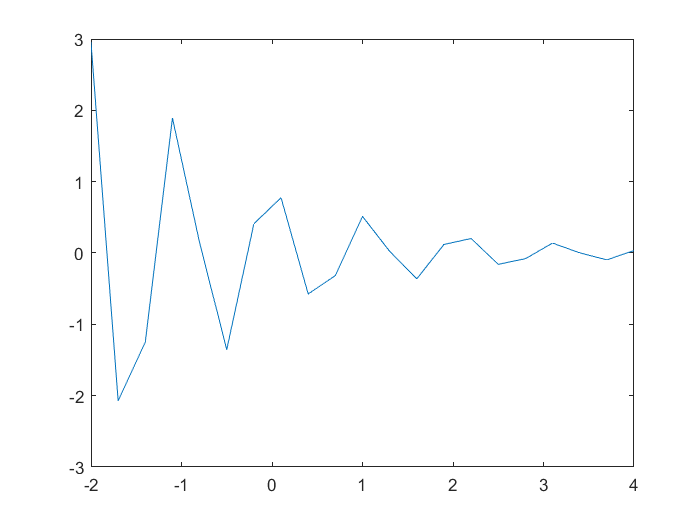

x=[-2:0.3:4];
y=3.5.^(-0.5*x).*cos(6*x);
plot(x, y)

그림을 좀 더 자세히 그리려면 x 값을 좀 더 촘촘히 발생시킨다.

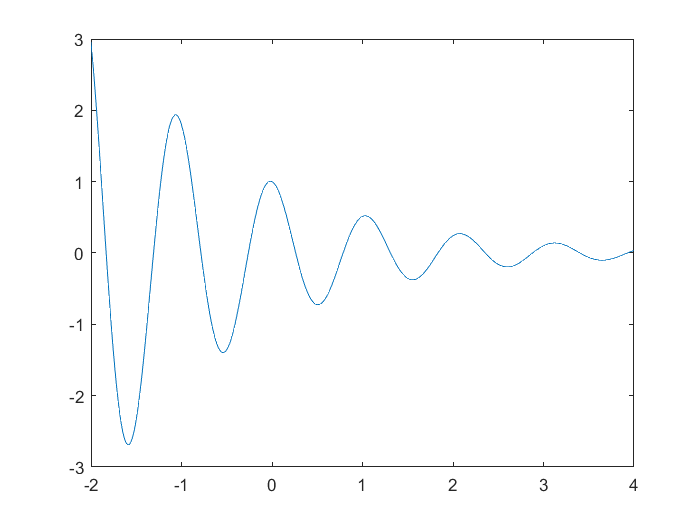

x=[-2:0.01:4];
y=3.5.^(-0.5*x).*cos(6*x);
plot(x, y)

5.3 동일 그래프에 다중 그래프 그리기

한 그래프에 여러 곡선을 표시하는 두 가지 방법 :

1. plot 명령어 속에 표시할 곡선 데이터를 나열하는 방법

2. hold on, hold off 명령어를 사용하는 그래프를 계속 그리는 방법

plot 명령어를 이용한 다중 그래프 출력

plot( X1, Y1, [LineSpec1], X2, Y2, [LineSpec2], X3, Y3, [LineSpec3] )

예

-2≤x≤4에 대해 함수 *y *= 3*x^*3 -26*x *+ 10 과 이 함수의 1차 도함수 및 2차 도함수 그래프를 같은 그림 창에 표시하라.

x=[-2:0.01:4];
y=3*x.^3-26*x+6;
yd=9*x.^2 - 26;
ydd = 18*x

ydd =   -36.0000  -35.8200  -35.6400  -35.4600  -35.2800  -35.1000  -34.9200  -34.7400  -34.5600  -34.3800  -34.2000  -34.0200  -33.8400  -33.6600  -33.4800  -33.3000  -33.1200  -32.9400  -32.7600  -32.5800  -32.4000  -32.2200  -32.0400  -31.8600  -31.6800  -31.5000  -31.3200  -31.1400  -30.9600  -30.7800  -30.6000  -30.4200  -30.2400  -30.0600  -29.8800  -29.7000  -29.5200  -29.3400  -29.1600  -28.9800  -28.8000  -28.6200  -28.4400  -28.2600  -28.0800  -27.9000  -27.7200  -27.5400  -27.3600  -27.1800


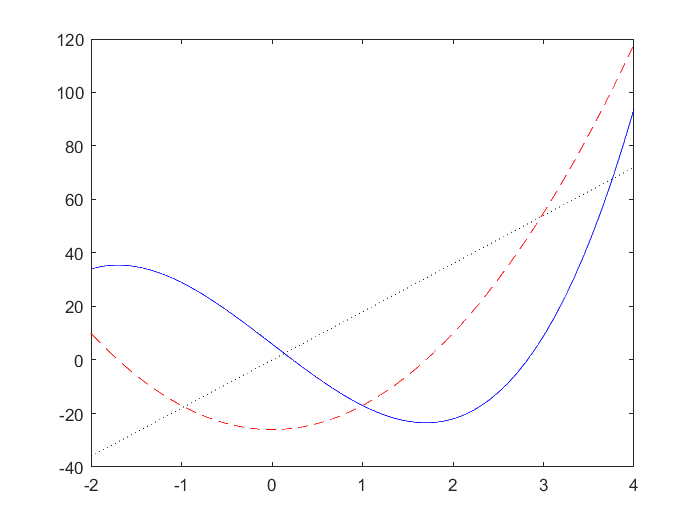

plot( x, y, '-b', x, yd, '--r', x, ydd, ':k' )

hold on/off 명령어를 이용한 다중 그래프 작성

1.plot 명령어를 이용하여 첫 번째 그래프를 그린다.

2. hold on 명령어를 입력한다. hold on 명령어는 첫 번째 그래프를 지우지 않고 유지하여 겹쳐그릴 수 있게 한다.

3. 이후부터 plot 명령어를 추가하면 현재 그래프에 곡선이 추가된다. 

4. hold off 명령어를 입력하여 겹쳐그리기 모드 해제 한다.

x=[-2:0.01:4];
y=3*x.^3-26*x+6;
yd=9*x.^2 - 26;
ydd = 18*x;
plot(x, y, '-b')
hold on
plot( x, yd,'--r')
plot( x, ydd,':k')
hold off